# WindRose

**Overview**

The `WindRose` chart manages the binning and display of speed and direction data (typically windspeed and direction). The data binning is performed on two levels: 

- The speed data is divided into 6 bins of equal length starting from 0 and covering the range of windspeeds.

- The direction data is divided into 36 bins of equal angular size (10 degrees).

Similar to a histogram or stacked bar chart, a wind rose shows the distribution and intensities of the speed values, arranged by direction. In contrast to a histogram or stacked bar chart, a wind rose displays the data in a circular (rather than linear) arrangement, enabling easy recognition of important directions. The radial values in the chart represent the percentage of observations falling into each combined speed/direction bin. The majority of the binning is performed by `histcounts`.

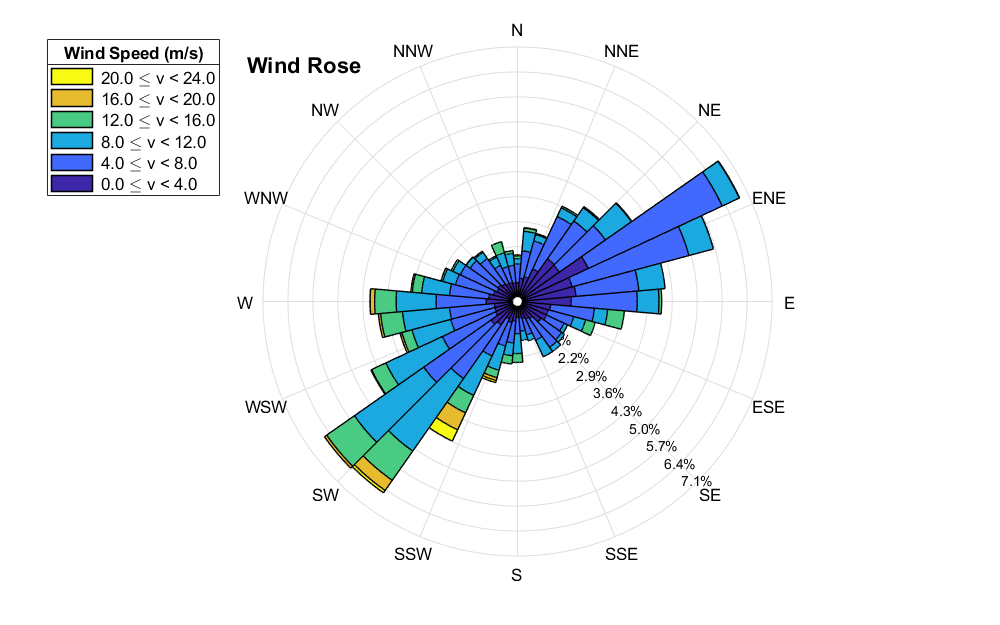

The chart data comprises a table `WindData` containing two variables:

- a nonnegative numeric vector `Speed`, and 

- a numeric vector `Direction` (taking values between 0 and 360 degrees). 

**Resources**

[Open](matlab: edit(fullfile(galleryRoot, '+Examples', 'WindRose.mlx'))) this Live Script to run and interact with the examples shown below.

[View](matlab: edit(fullfile(galleryRoot, '+Charts', 'WindRose'))) the source code for the `WindRose` chart.

Documentation for [histcounts](matlab: web(fullfile(matlabroot, 'help', 'matlab', 'ref', 'histcounts.html'), '-helpbrowser')).

Copyright 2018 The MathWorks, Inc.

## Import the chart.

import Charts.WindRose

## Load the data.

load( fullfile( galleryRoot(), '+Data', 'WindData.mat' ) )

## Create a figure for the chart.

f = galleryFigure( 'Name', 'Wind Rose Example', ...
                   'Position', [0.25, 0.25, 0.50, 0.50] );

## Create the chart.

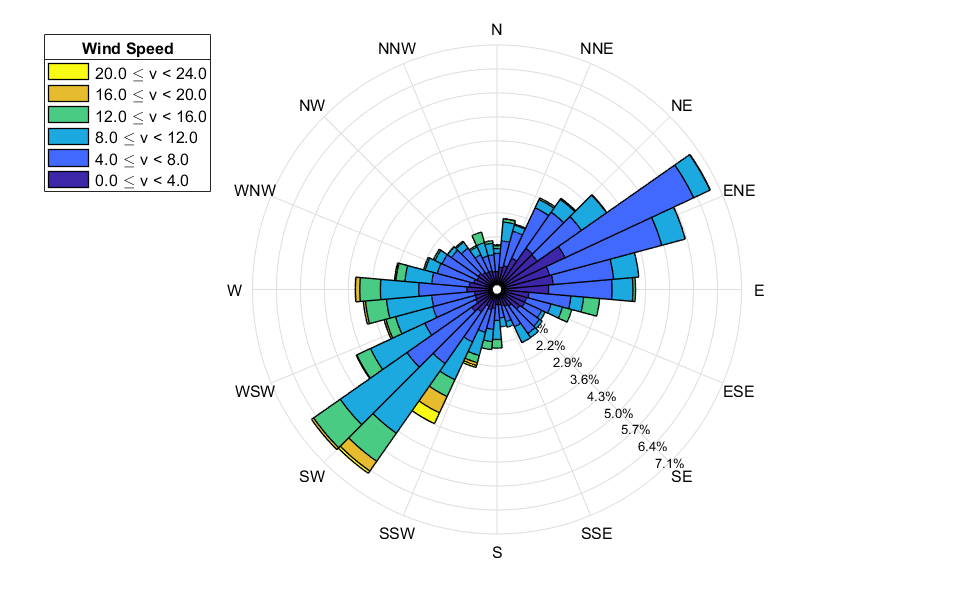

WR = WindRose( 'Parent', f, 'WindData', W );

## Customize the appearance of the chart.

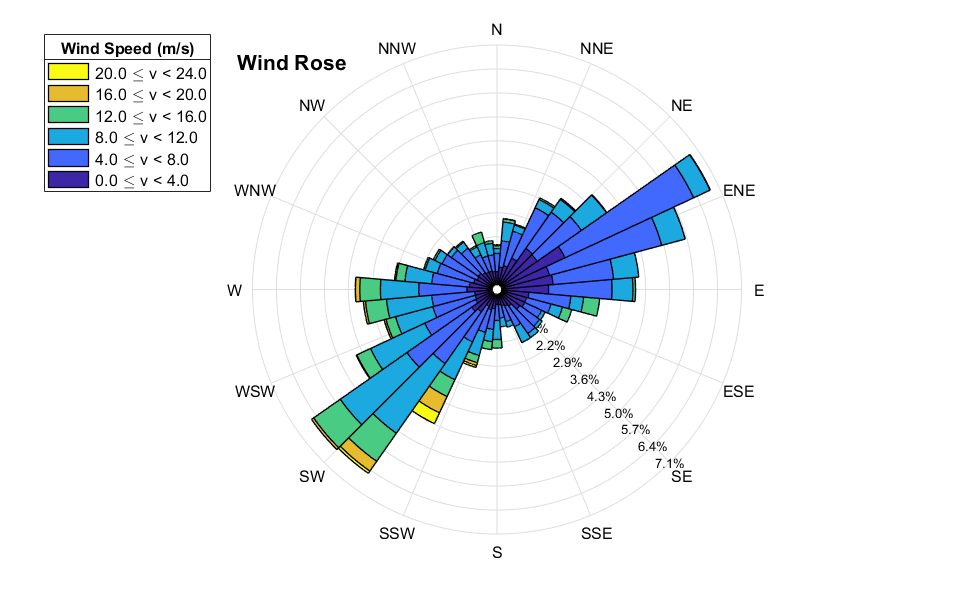

WR.LegendTitle.String = 'Wind Speed (m/s)';
WR.Title.String = 'Wind Rose';
WR.Title.FontSize = 16;
WR.Title.Position(1:2) = [WR.Title.Position(1)-6, WR.Title.Position(2)-1];

## Change the chart data.

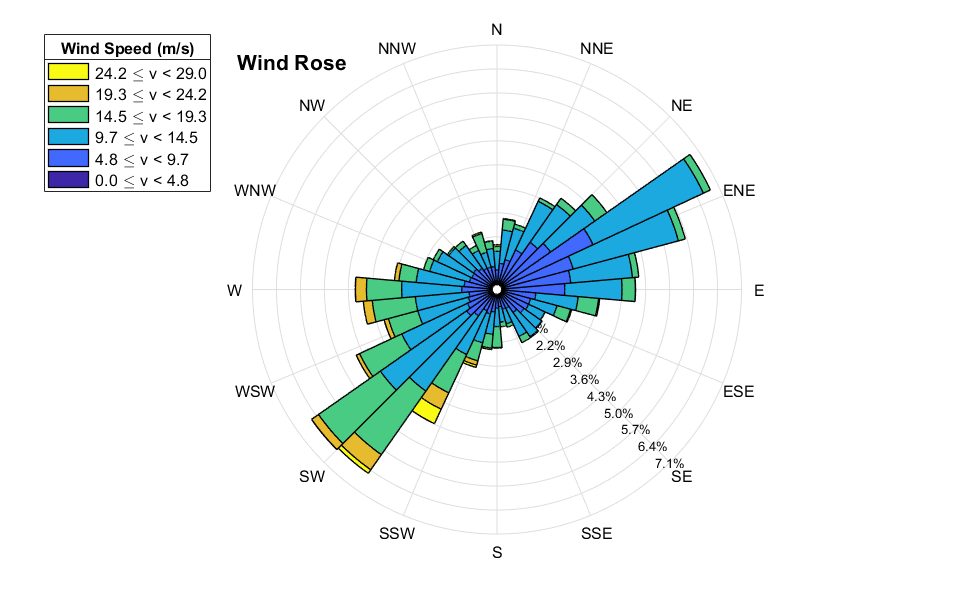

WR.WindData.Speed = WR.WindData.Speed + 5;

## Change the speed and direction data together.

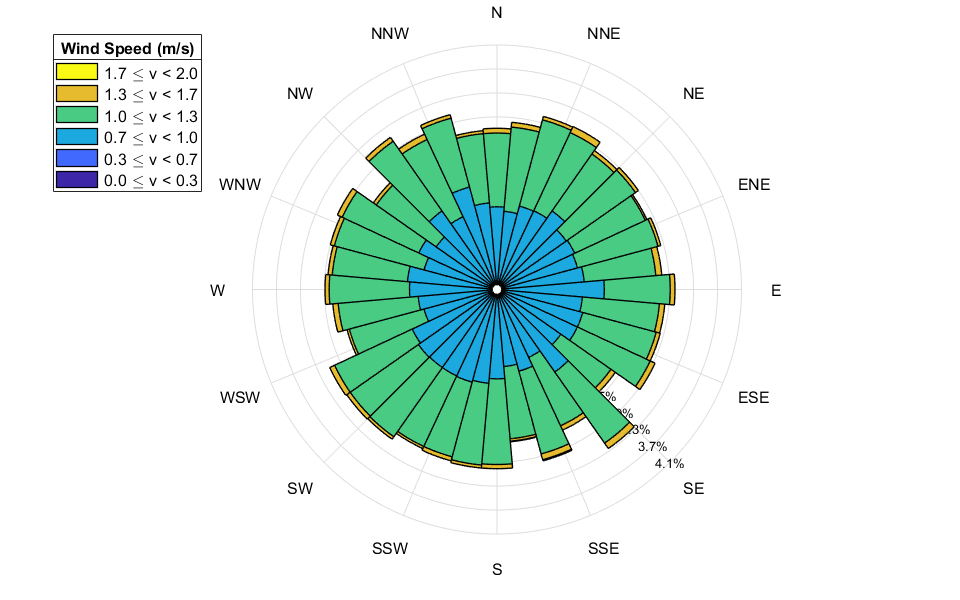

rng default
direction = 360 * rand( 10000, 1 );
speed = exp( 0.15 * randn( size( direction ) ) );
newWindData = table( direction, speed, 'VariableNames', {'Direction', 'Speed'} );
WR.WindData = newWindData;

## Adjust the position of the chart title.

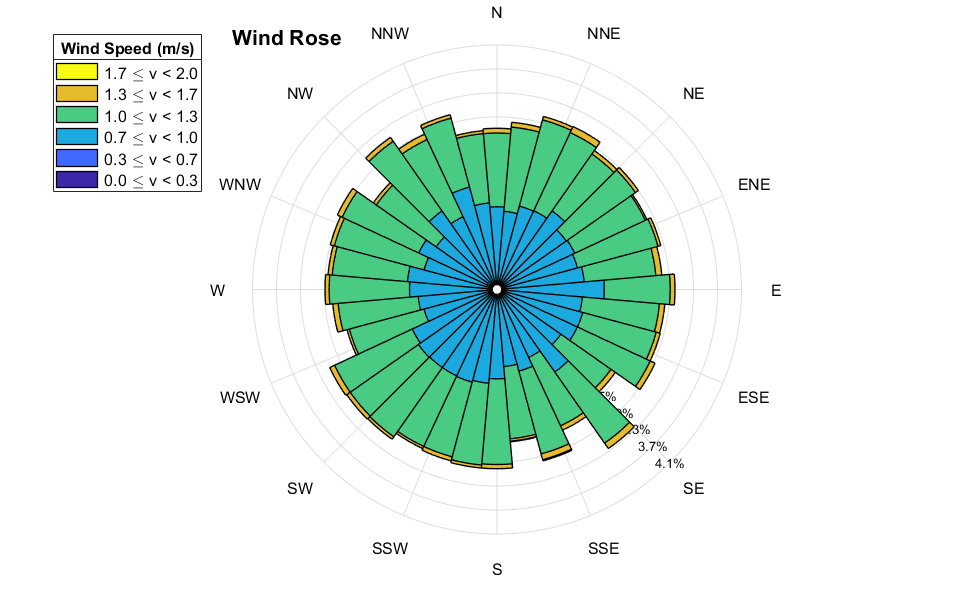

WR.Title.Position(1:2) = [-WR.MaxRadius+0.5, WR.MaxRadius];